# Production noise as a dataset

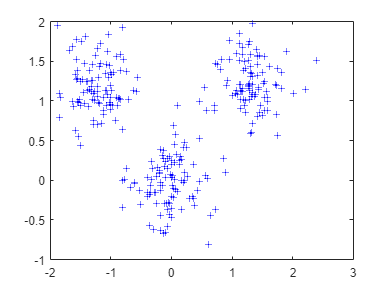

rng(2);  %Fixed random seeds
%%First set of data
mu1=[0 0];  %Mean value
S1=[0.1 0 ; 0 0.1];  %covariance value
data1=mvnrnd(mu1,S1,100);   %Generate Gaussian distribution data
%%Second set of data
mu2=[-1.25 1.25];
S2=[0.1 0 ; 0 0.1];
data2=mvnrnd(mu2,S2,100);
%%Third set of data
mu3=[1.25 1.25];
S3=[0.1 0 ; 0 0.1];
data3=mvnrnd(mu3,S3,100);
%%Data Visualization
figure
plot(data1(:,1),data1(:,2),'b+');
hold on;
plot(data2(:,1),data2(:,2),'b+');
plot(data3(:,1),data3(:,2),'b+');

%%Three sets of data stitching
data = [data1;data2;data3];

Calling the KMRGC function

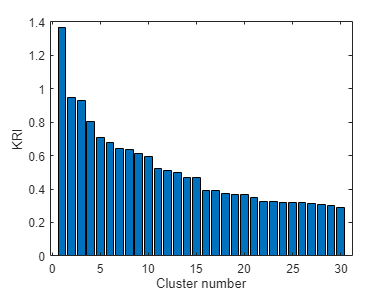

num = data;
KMRGC_result = kmrgcdemo(num,10); %采用KMRGC实现数据的聚类，以元胞的形式存放不同簇内样本，其中样本为原始数据的列数。

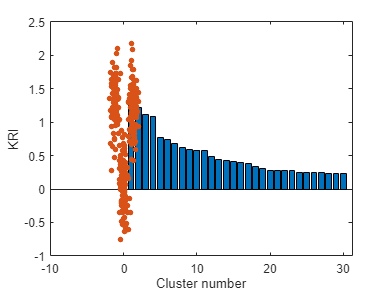

%% 将不同簇按照数字进行标记。
[m,n] = size(num);
data4 = zeros(m,1);
for i = 1:length(KMRGC_result)
    data4(cell2mat(KMRGC_result(1,i))) = i;
end

%% Visualization
figure;
scatter(num(:,1),num(:,2),20,data4,'filled');
colormap("lines");

Calling the MRGC function

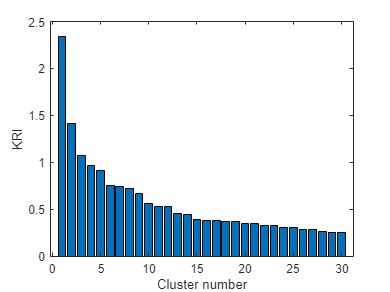

num = data;
KMRGC_result = mrgcdemo(num,19); %采用KMRGC实现数据的聚类，以元胞的形式存放不同簇内样本，其中样本为原始数据的列数。

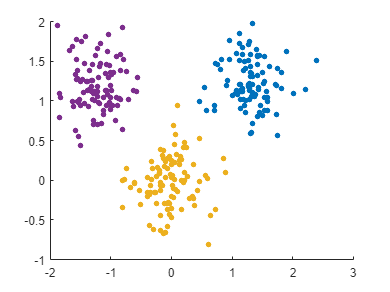

%% 将不同簇按照数字进行标记。
[m,n] = size(num);
data5 = zeros(m,1);
for i = 1:length(KMRGC_result)
    data5(cell2mat(KMRGC_result(1,i))) = i;
end
%% Visualization
figure;
scatter(num(:,1),num(:,2),20,data5,'filled');
colormap("lines");

### K-means clustering

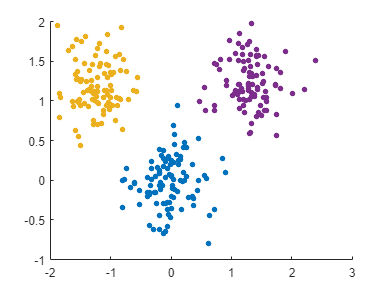

[idx1,C] = kmeans(num,3); %聚类
%-------------------------------------------------------------------------
figure;
scatter(num(:,1),num(:,2),20,idx1,'filled');
colormap("lines");

## Generate circle-shaped data sets

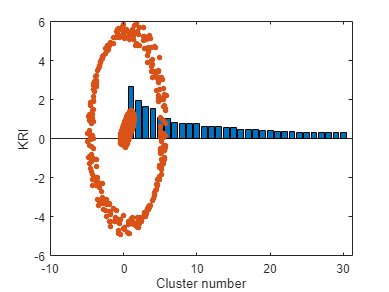

rng('default') % For reproducibility

% Parameters for data generation
N = 300;  % Size of each cluster
r1 = 0.5; % Radius of first circle
r2 = 5;   % Radius of second circle
theta = linspace(0,2*pi,N)';

X1 = r1*[cos(theta),sin(theta)]+ rand(N,1); 
X2 = r2*[cos(theta),sin(theta)]+ rand(N,1);
X = [X1;X2]; % Noisy 2-D circular data set
scatter(X(:,1),X(:,2),20,'filled')

### MRGC clustered circle type dataset

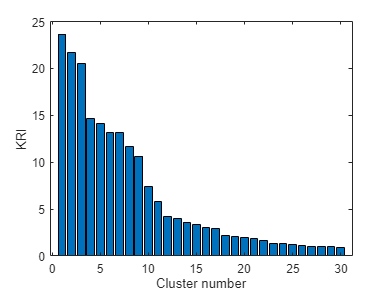

gg1 = mrgcdemo(X,30);

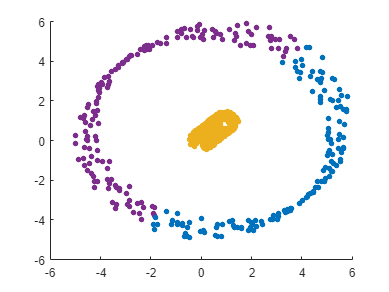

[m,n] = size(X);
data4 = zeros(m,1);
for i = 1:length(gg1)
    data4(cell2mat(gg1(1,i))) = i;
end
figure;
scatter(X(:,1),X(:,2),20,data4,'filled');
colormap("lines");

### KMRGC clustered circle type dataset

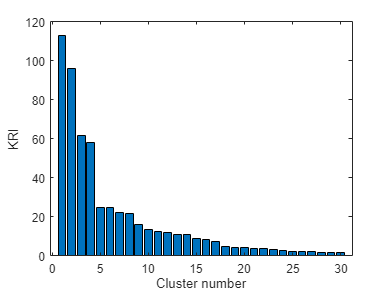

gg2 = kmrgcdemo(X,60);

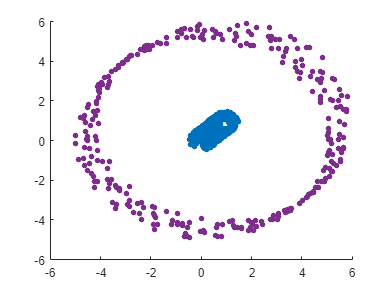

[m,n] = size(X);
data4 = zeros(m,1);
for i = 1:length(gg2)
    data4(cell2mat(gg2(1,i))) = i;
end
figure;
scatter(X(:,1),X(:,2),20,data4,'filled');
colormap("lines");

### K-means clustered circle type dataset

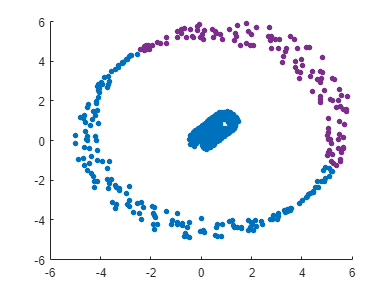

[idx1,C] = kmeans(X,2); %聚类
%-------------------------------------------------------------------------
figure;
scatter(X(:,1),X(:,2),20,idx1,'filled');
colormap("lines");